%{
    This script performs the state detection to extract the pulse data.
    It calls uses the function fnStateDetection which does the processing.
    Here the data is combined into in an array and the pulses that are too
    short to be real pulses are discarded.
%}

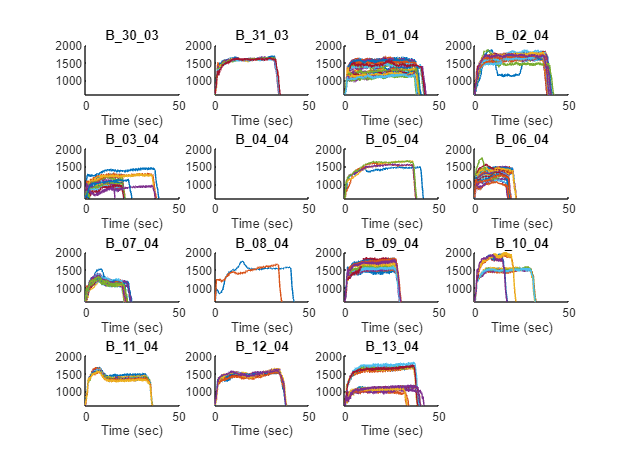

printFigures = false;
pulseThreshold = 600; % Threshold for state detection given by company
minPulseTimeThreshold = 500; % Samples

% Loop through the files, load the data the perform the state detection
% Extract the pulses for each sensor signal based on Signal 20
signalNumberForDetection = 5;
signalNumberToPlot = 5; % This is signal 21:20
[~,numOfFiles] = size(filenames);
mask = {numOfFiles};
flag = {numOfFiles};
pulseData = {numOfFiles};
rawDataArray = {numOfFiles};
totalPulses = 1;
numOffalsePulses = 0;

for fileIndex=1:numOfFiles
    % Load the data for the current file
    rawDataStruct =  load(dataSubfolder + filenames(fileIndex) + ".mat");
    rawDataArray{fileIndex} = struct2array(rawDataStruct); 

    %pulses is a 2D array with dimensions (1 * numOfPulses)
    [pulseData{fileIndex}, mask{fileIndex}, flag{fileIndex}, maxPulseLengths(fileIndex)] = fnStateDetection(rawDataArray{fileIndex}, pulseThreshold, minPulseTimeThreshold, signalNumberForDetection);
    
    % Plot the extracted Signal 20 pulses for this particular file
    subplot(4, 4, fileIndex);
    hold on;
    [~, numOfPulses] = size(pulseData{fileIndex});
    for pulseIndex=1:numOfPulses
        x = pulseData{fileIndex}{pulseIndex}(:, signalNumberToPlot);
        t = 0 : Ts : (Ts * size(x, 1) - Ts);
        plot(t, x);
    end
    title(filenames(fileIndex), 'Interpreter', 'none');
    xlabel("Time (sec)");
    axis([0 50 pulseThreshold 2000])

    % Combine the pulse data for this file with all the others 
    for pulseIndex = 1:numOfPulses
        if flag{fileIndex}(pulseIndex) == false % Only include pulses that aren't marked as potential false ones
            for sensorIndex = 1:numOfSignals % Add data for each sensor
                tempData = pulseData{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
            end
            totalPulses = totalPulses + 1;
        else
            numOffalsePulses = numOffalsePulses + 1;
        end
    end
end

if saveFigures
    print -depsc '..\Latex Document\figures\IdentifiedPulsesFig';
end

%% Remove DC Offset
%% Pad to the length of longest pulse
maxPulseLength = max(maxPulseLengths) + 1;
for fileIndex = 1:numOfFiles
    for pulseIndex = 1:size(pulseData{fileIndex},2)
        temp = pulseData{fileIndex}{pulseIndex};
        numSamplesUnderMax = maxPulseLength - size(temp, 1);
        pulseData_DcRemoved{fileIndex}{pulseIndex} = temp - mean(temp, 1);
        pulseData_Padded{fileIndex}{pulseIndex} = padarray (temp, numSamplesUnderMax, 12, "post");
        temp2 = pulseData_Padded{fileIndex}{pulseIndex};
        pulseData_DcRemovedPadded{fileIndex}{pulseIndex} = temp2 - mean(temp2, 1);
    end
end
clear temp;
clear temp2;

%% Combine the data for all padded pulses
totalPulses = 1;
for fileIndex=1:numOfFiles
    for pulseIndex = 1:size(pulseData{fileIndex},2)
        if flag{fileIndex}(pulseIndex) == false % Only include pulses that aren't marked as potential false ones
            for sensorIndex = 1:numOfSignals % Add data for each sensor
                tempData = pulseData_Padded{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable_Padded{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
                tempData = pulseData_DcRemoved{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable_DcRemoved{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
                tempData = pulseData_DcRemoved{fileIndex}{pulseIndex}(:, sensorIndex);
                pulseData_Timetable_DcRemovedPadded{totalPulses, sensorIndex} = timetable(tempData, 'SampleRate', 1/Ts, 'VariableNames', sensorNames(sensorIndex));
            end
            totalPulses = totalPulses + 1;
        end
    end
end
clear fileIndex;
clear pulseIndex;
clear tempData;

## Plot padded data

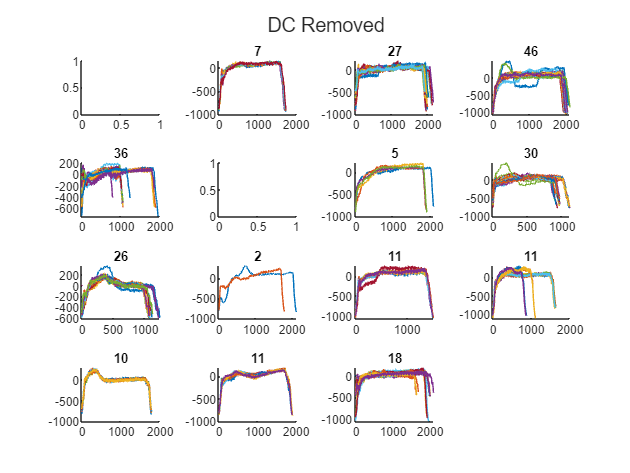

figure();
fig = tiledlayout(4, 4);
%title(fg, 'Padded data');
title(fig, 'DC Removed');
for fileIndex=1:numOfFiles
    nexttile; hold on;
    for pulseIndex = 1:size(pulseData_Padded{fileIndex},2)
        %plot( pulseData_Padded{fileIndex}{pulseIndex}(:,5) );
        plot( pulseData_DcRemoved{fileIndex}{pulseIndex}(:,5) );
        title( pulseIndex );
    end
end

clear fileIndex;
clear pulseIndex;
clear fig;

## Plot the state detection signal vs 21:20 Actual Moment under Rollers

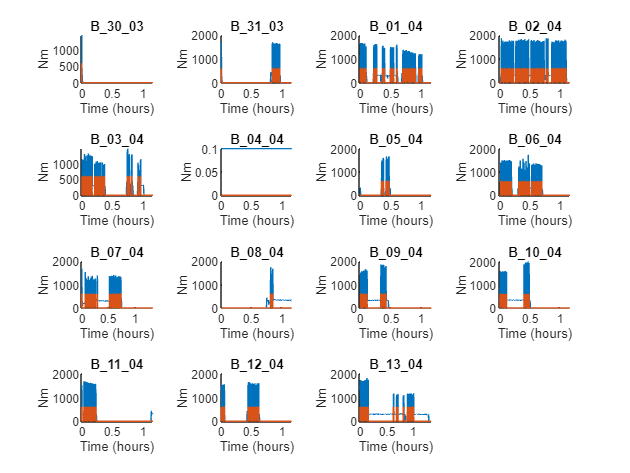

figure();
fig = tiledlayout(4, 4);
%title(fig, 'State detection signal 21:20 Actual Moment under Rollers');
for fileIndex=1:numOfFiles
    nexttile; hold on;
    x = cell2mat(rawDataArray{fileIndex}(signalNumberToPlot, 2));
    t = 0 : Ts / 3600 : (Ts * size(x, 1) - Ts) / 3600;
    plot(t, x');
    plot(t, mask{fileIndex});
    title(filenames(fileIndex), 'Interpreter', 'none');
    xlabel("Time (hours)");
    ylabel("Nm");
end


if saveFigures
    print -depsc '..\Latex Document\figures\StateDetectionFig';
end

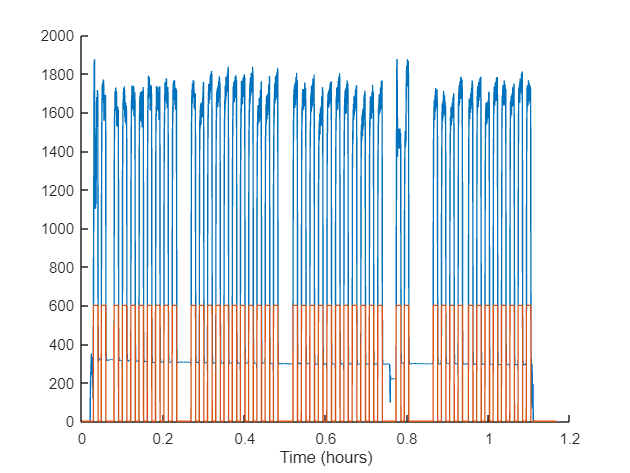

figure(); hold on;
x = cell2mat(rawDataArray{4}(signalNumberToPlot, 2));
t = 0 : Ts / 3600 : (Ts * size(x, 1) - Ts) / 3600;
plot(t, x');
plot(t, mask{4});
%title("State detection for " + filenames(4), 'Interpreter', 'none');
xlabel("Time (hours)");


if saveFigures
    print -depsc '..\Latex Document\figures\StateDetectionFig_B_02_04';
end

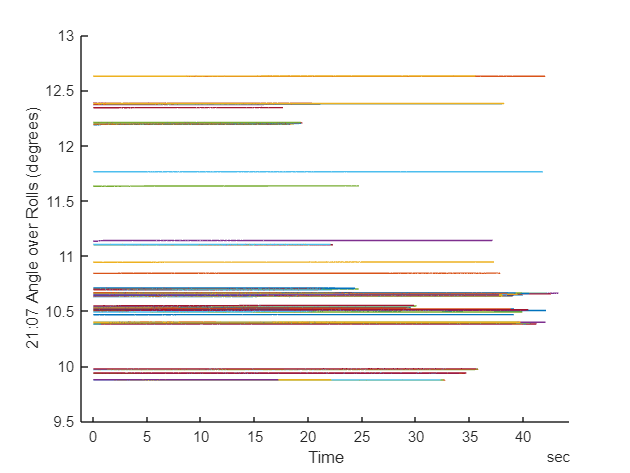

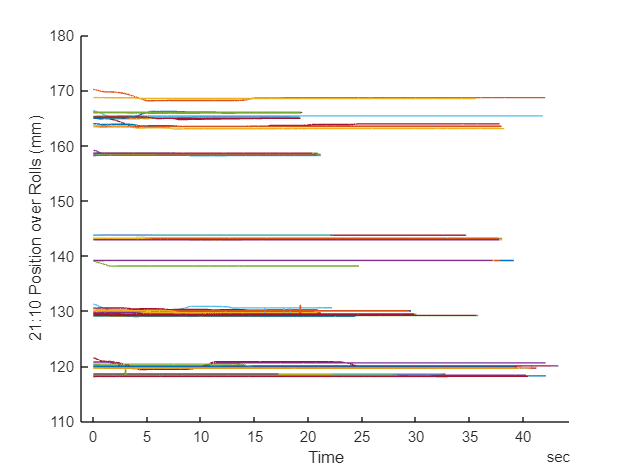

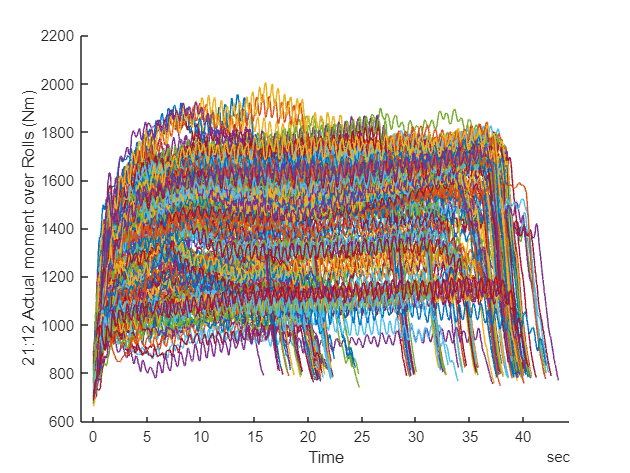

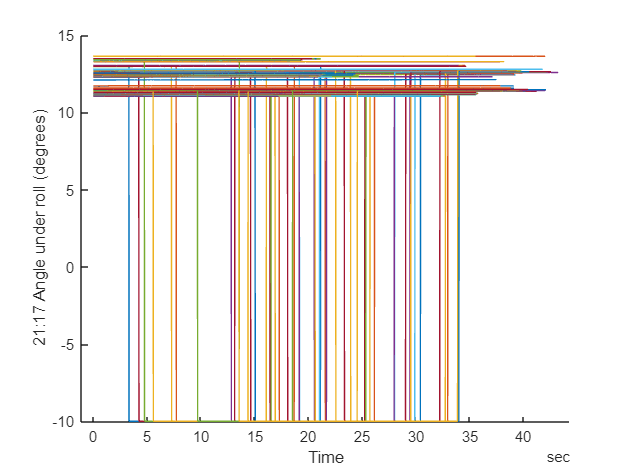

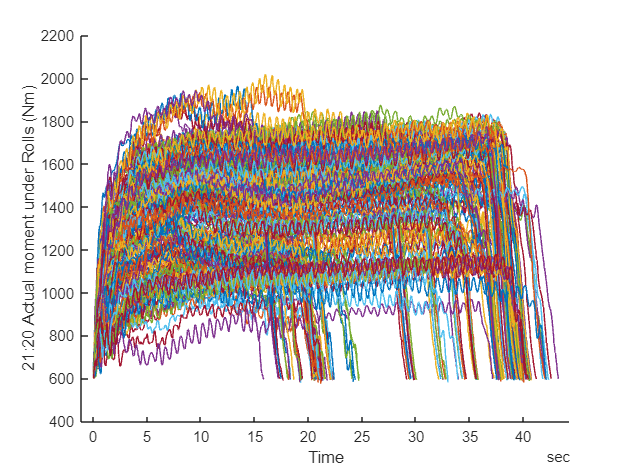

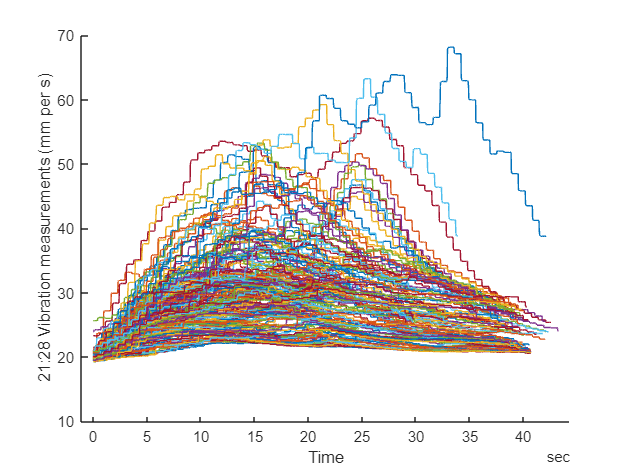

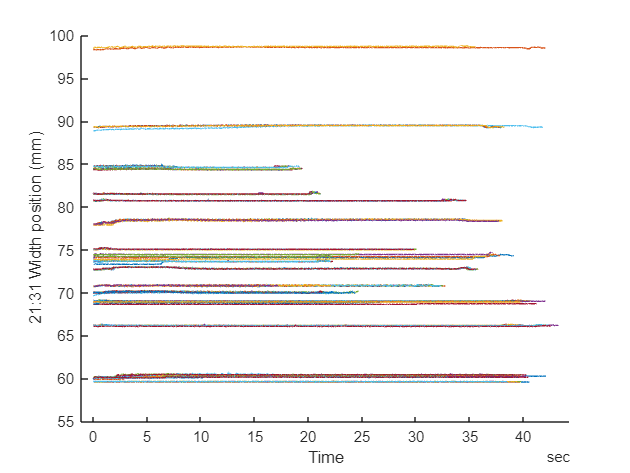

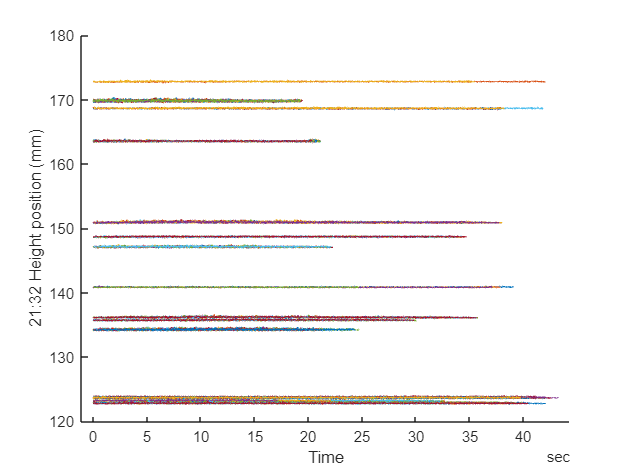

numOfPulses = totalPulses - 1;
for signalIndex = 1:numOfSignals        
    figure(); hold on; 
    for pulseIndex=1:numOfPulses
        plot(pulseData_Timetable{pulseIndex, signalIndex}, 1, 'LineWidth', 0.2);
    end
    filename = "..\Latex Document\figures\SignalPulse" + signalIndex;
    if (saveFigures == true)
        print(filename,'-depsc','-tiff')
    end
end

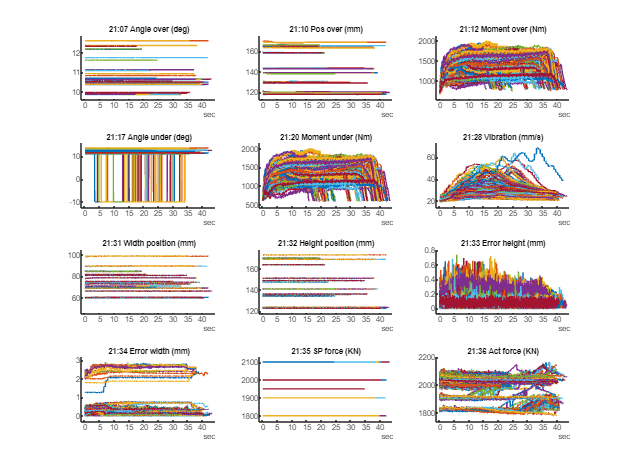

fig = tiledlayout(4, 3);
for signalIndex = 1:numOfSignals        
    nexttile; hold on; 
    str1 = char(sensorNames(signalIndex));
    str2 = sensorUnits(signalIndex);
    title (str1(1:5) + " " + str2);    
    for pulseIndex=1:numOfPulses
        plot(pulseData_Timetable{pulseIndex, signalIndex}, 1, 'LineWidth', 0.05);
    end
    ylabel("");
    xlabel("");

    lims = ylim();
    range = lims(end) - lims(1);
    newLims = [lims(1)-0.1*range lims(end)+0.1*range];
    ylim(newLims);

%     ax = gca;
%     yt = ax.YTick;
%     newTicks = [yt(1) yt(end)];
%     yticks(newTicks);
end

width = 10;
height = 10;
fontsize = 6;
set(gcf,'paperunits','centimeters')
set(gcf, 'PaperPositionMode', 'manual');
set(gcf,'papersize',[width,height])
set(gcf,'paperposition',[0,0,width,height])
set(gcf, 'renderer', 'painters');
set(findall(gcf,'-property','FontSize'),'FontSize',5);

filename = "..\Latex Document\figures\SignalPulses";
if saveFigures
    print(filename,'-depsc','-tiff')
end

clear x;
clear t;
clear signalNumberToPlot;
clear maxPulseLength;
clear maxPulseLengths;
clear minPulseTimeThreshold;
clear fig;
clear fileIndex;